# Single Sine Excitation of a Nonlinear Activation Unit: Small Gain Signals

Mauro J. Sanchirico III

## Setup

clc; clear; close all;
SetDefaultPlotParameters;

## Problem

A nonlinear activation unit with input gain $\gamma \text{ }$ is defined:


$$\varphi \left(v\right)=tanh\left(\gamma \text{ }v\right)$$


For input signal $v=sin\left(\omega t+\phi \text{ }\right)$ we wish to know the Fourier Series of the output signal $y=\varphi \left(v\right)$

That is we want to know the Fourier Series:


$$y\left(t\right)=tanh\left(\gamma \text{ }sin\left(\omega t+\phi \text{ }\right)\right)$$


For now, we restrict out analysis to small gains $|\gamma |<\frac{\pi }{2}$.

## Taylor Series Expansion

Let $x=\omega t+\phi$.  Since $|\gamma |<\frac{\pi }{2}$ we may take the Taylor Series expansion of $tanh\left(v\right)$:


$$y\left(x\right)=\sum_{m=1}^{\infty } a_m {\left(\gamma \text{ }sin\left(x\right)\right)}^{2m−1}$$



$$y\left(x\right)=\sum_{m=1}^{\infty } {a }_m {\gamma \text{ }}^{2m−1} {sin}^{2m−1} \left(x\right)$$


Where:


$$a_m =\frac{2^{2m} \left(2^{2m} −1\right)B_{2m} }{\left(2m\right)!}$$


## Power Reduction Formula

We may apply the power reduction formula to reduce the $\sin^{2m−1} \left(x\right)$ factor to a trigonometric polynomial.  The applicable power reduction formula is given via rule 1.320.3 on page 31 (PDF page 80) of Gradshteyn and Ryzik:


$${sin}^{2m−1} \left(x\right)=\frac{1}{2^{2m−2} }\sum_{k=0}^{m−1} {\left(−1\right)}^{m+k−1} C_k^{2m−1} sin\left(\left(2m−2k−1\right)x\right)$$


Thus:


$$y\left(x\right)=\sum_{m=1}^{\infty } a_m {\gamma \text{ }}^{2m−1} \frac{1}{2^{2m−2} }\sum_{k=0}^{m−1} {\left(−1\right)}^{m+k−1} C_k^{2m−1} sin\left(\left(2m−2k−1\right)x\right)$$



$$y\left(x\right)=\sum_{m=1}^{\infty } \sum_{k=0}^{m−1} a_m \frac{{\left(−1\right)}^{m+k−1} {{\gamma \text{ }}^{2m−1} C}_k^{2m−1} }{2^{2m−2} }\sin \left(\left(2m−2k−1\right)x\right)$$


Substituting the definition of $a_m$:


$$y\left(x\right)=\sum_{m=1}^{\infty } \sum_{k=0}^{m−1} \frac{{\left(−1\right)}^{m+k−1} 2^{2m} \left(2^{2m} −1\right){{\gamma \text{ }}^{2m−1} C}_k^{2m−1} B_{2m} }{2^{2m−2} \left(2m\right)!}\sin \left(\left(2m−2k−1\right)x\right)$$


syms m
simplify(2^(2*m) / 2^(2*m-2))

$$ans = 4$$

Simplifying we have:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

***Theorem 1:***


$$y\left(x\right)=\sum_{m=1}^{\infty } \sum_{k=0}^{m−1} \frac{{\left(−1\right)}^{m+k−1} 4\left(2^{2m} −1\right){{\gamma \text{ }}^{2m−1} C}_k^{2m−1} B_{2m} }{\left(2m\right)!}\sin \left(\left(2m−2k−1\right)x\right)$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Now, notice that the frequencies ${\omega^∗ }_{m,k} =2m−2k−1$ form a pattern:


$$\left\lbrace \left\lbrace 1\right\rbrace ,\left\lbrace 3,1\right\rbrace ,\left\lbrace 5,3,1\right\rbrace ,\left\lbrace 7,5,3,1\right\rbrace ,\left\lbrace 9,7,5,3,1\right\rbrace ,\text{ }\left\lbrace 11,9,7,5,3,1\right\rbrace ,\ldotp \ldotp \ldotp \right\rbrace$$


%
%     +---+-----+-------+---------+-----
% m = | 1 | 2 2 | 3 3 3 | 4 4 4 4 | ...
%     +---+-----+-------+---------+-----
% k = | 0 | 0 1 | 0 1 2 | 0 1 2 3 | ...
%     +---+-----+-------+---------+-----
% w = | 1 | 3 1 | 5 3 1 | 7 5 3 1 | ...
%     +---+-----+-------+---------+-----
%
% Rearranging this table we have:
%
% w = 1     3     5     7
%
%     1,0   2,0   3,0   4,0
%     2,1   3,1   4,1
%     3,2   4,2
%     4,3
%

Define a function yeilding the coefficient $\xi \text{ }$ associated with the$m,k$pair:


$$\xi \text{ }\left(m,k\right)=\frac{{\left(−1\right)}^{m+k−1} 4\left(2^{2m} −1\right){{\gamma \text{ }}^{2m−1} C}_k^{2m−1} B_{2m} }{\left(2m\right)!}$$


Now notice that due to the pattern above, we can evaluate the coefficient associated with each $\omega_n =2n−1$


$$y\left(x\right)=\sum_{n=1}^{\infty } c_n sin\left(\left(2n−1\right)x\right)$$


Where:


$$c_n =\sum_{m=n}^{\infty } \xi \text{ }\left(m,m−n\right)$$


Expanding:


$$y\left(x\right)=\sum_{n=1}^{\infty } \sum_{m=n}^{\infty } \frac{{\left(−1\right)}^{m+k−1} 4\left(2^{2m} −1\right){{\gamma \text{ }}^{2m−1} C}_k^{2m−1} B_{2m} }{\left(2m\right)!}\sin \left(\left(2n−1\right)x\right);k=m−n$$


Substituting $k=m−n$:


$$y\left(x\right)=\sum_{n=1}^{\infty } \sum_{m=n}^{\infty } \frac{{\left(−1\right)}^{m+\left(m−n\right)−1} 4\left(2^{2m} −1\right){{\gamma \text{ }}^{2m−1} C}_{m−n}^{2m−1} B_{2m} }{\left(2m\right)!}\sin \left(\left(2n−1\right)x\right)$$



$$y\left(x\right)=\sum_{n=1}^{\infty } \sum_{m=n}^{\infty } \frac{{\left(−1\right)}^{2m−n−1} 4\left(2^{2m} −1\right){{\gamma \text{ }}^{2m−1} C}_{m−n}^{2m−1} B_{2m} }{\left(2m\right)!}\sin \left(\left(2n−1\right)x\right)$$


Thus we arrive at Theorem 2, which gives the sine series expansion of $tanh\left(\gamma sin\left(x\right)\right)$

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

***Theorem 2:***


$$y\left(x\right)=\sum_{n=1}^{\infty } \sum_{m=n}^{\infty } \frac{{\left(−1\right)}^{2m−n−1} 4\left(2^{2m} −1\right){{\gamma \text{ }}^{2m−1} C}_{m−n}^{2m−1} B_{2m} }{\left(2m\right)!}\sin \left(\left(2n−1\right)x\right)$$



$$y\left(x\right)\approx \sum_{n=1}^{M} \sum_{m=n}^{M} \frac{{\left(−1\right)}^{2m−n−1} 4\left(2^{2m} −1\right){{\gamma \text{ }}^{2m−1} C}_{m−n}^{2m−1} B_{2m} }{\left(2m\right)!}\sin \left(\left(2n−1\right)x\right)$$


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Testing the Result

Here we see the Fourier Series expansion of $y=tanh\left(\gamma \text{ }sin\left(x\right)\right)$to $m=1\ldotp \ldotp \ldotp 5$.

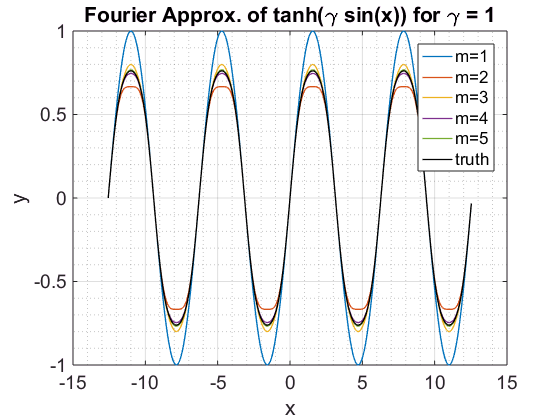

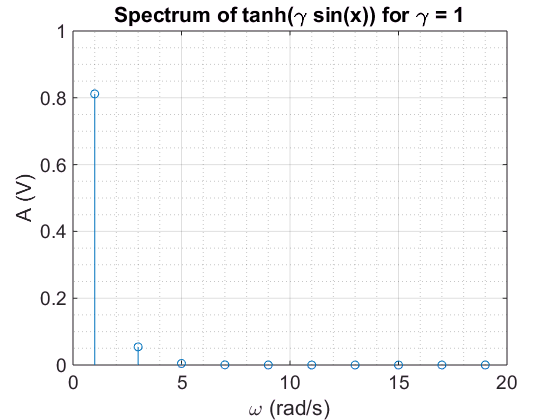

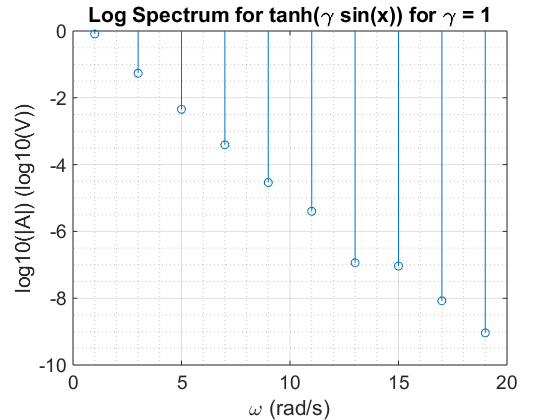

AnalyzeFourierSeries

## Algorithms

function y = EvaluateFourierSineSeries(a, omega, x)
    y = zeros(size(x));
    for idx = 1:length(a)
        y = y + a(idx)*sin(omega(idx).*x);
    end
end

% @breif Analytic computation of the fourier series of tanh(gamma*sin(x))
% using Theorem 1.
function [a, omega] = GetFourierSeriesTanhSin1(model_order, gamma)
    a = [];
    omega = [];
    for m=1:model_order
        for k=0:m-1
            q_num = (-1)^(m+k-1)*4*(2^(2*m)-1)*gamma^(2*m-1);
            q_denom = (factorial(2*m));
            q = q_num/q_denom;
            c = nchoosek(2*m-1, k);
            b = bernoulli(2*m);
            
            a(end+1) = q*c*b;
            omega(end+1) = 2*m-2*k-1;
        end
    end 
end

% @breif Analytic computation of the fourier series of tanh(gamma*sin(x))
% using Theorem 2.
function [a, omega] = GetFourierSeriesTanhSin2(model_order, gamma)
    a = [];
    omega = [];
    for n=1:model_order
        a_n = 0;
        for m=n:model_order
            q_num = (-1)^(2*m-n-1)*4*(2^(2*m)-1)*gamma^(2*m-1);
            q_denom = factorial(2*m);
            q = q_num/q_denom;
            c = nchoosek(2*m-1, m-n);
            b = bernoulli(2*m);
            a_n = a_n + q*c*b;
        end
        a(end+1) = a_n;
        omega(end+1) = 2*n-1;
    end 
end


function AnalyzeFourierSeries
    gamma = 1;
    x = -4*pi:0.1:4*pi;
    y_truth = tanh(gamma*sin(x));
    legend_strs = {};
    
    for m = 1:10
        [a{m}, omega{m}] = GetFourierSeriesTanhSin2(m, gamma);
        y_sines{m} = EvaluateFourierSineSeries(a{m}, omega{m}, x);
    end
    
    figure;
    
    for m = 1:5
        plot(x, y_sines{m});
        hold on;
        legend_strs{end+1} = sprintf('m=%i', m);
    end
    
    legend_strs{end+1} = sprintf('truth');
    plot(x, y_truth, 'k');
    grid minor
    legend(legend_strs);
    xlabel('x');
    ylabel('y');
    title('Fourier Approx. of tanh(\gamma sin(x)) for \gamma = 1');
    
    figure;
    stem(omega{10}, a{10});
    hold on;
    grid minor
    xlabel('\omega (rad/s)');
    ylabel('A (V)');
    title('Spectrum of tanh(\gamma sin(x)) for \gamma = 1');
    
    figure;
    stem(omega{10}, log10(abs(a{10})));
    hold on;
    grid minor
    xlabel('\omega (rad/s)');
    ylabel('log10(|A|) (log10(V))');
    title('Log Spectrum for tanh(\gamma sin(x)) for \gamma = 1');
    
end


function SetDefaultPlotParameters
set(0, 'DefaultAxesFontSize', 14, ...
       'DefaultTextFontSize', 14, ...
       'DefaultAxesFontName', 'Arial', ...
       'DefaultTextFontName', 'Arial', ...
       'DefaultAxesXGrid','on', ...
       'DefaultAxesYGrid','on', ...
       'DefaultLineLineWidth', 1);
end